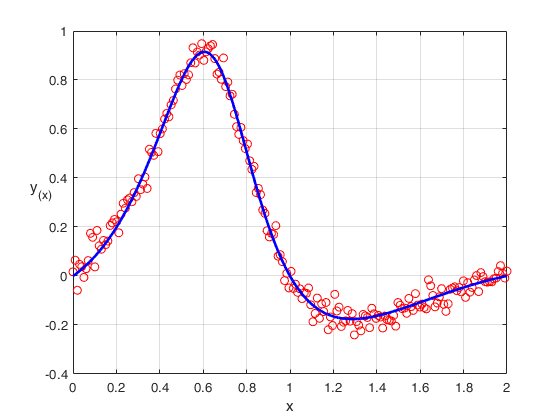

clear;
% func = @(x) (sin(3.*x+2));              % funkce pro nagenerování dat
func = @(x,x2) (sin(pi.*x))./((x2.^2)+1);   % funkce pro nagenerování dat
from = 0;                               % rozsah pro od ...
to = 4;                                 % ... do pro nagenerování dat
from2 = 0;                               % rozsah pro od ...
to2 = 4;
N =  200;                               % počet vzorků
x = from:((to-from)/(N-1)):to;          % vzorkovací čas
x2 = from2:((to2-from2)/(N-1)):to2;
y = awgn(func(x,x2),30);                   % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)
plot(x,y,'or');
hold on;
grid on;
xlabel("x");
ylabel("y_{(x)}","Rotation",0);
plot(from:((to-from)/(N*10-1)):to,func(from:((to-from)/(N*10-1)):to,from2:((to2-from2)/(N*10-1)):to2),'-b',"LineWidth",2);
hold off;

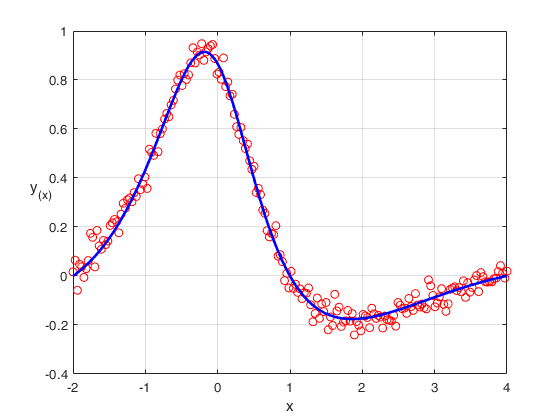

plot(x2,y,'or');
hold on;
grid on;
xlabel("x");
ylabel("y_{(x)}","Rotation",0);
plot(from2:((to2-from2)/(N*10-1)):to2,func(from:((to-from)/(N*10-1)):to,from2:((to2-from2)/(N*10-1)):to2),'-b',"LineWidth",2);

csvwrite('input_data.csv',[x;x2;y]); 